# Ejercicio 2 (2 puntos). Transformadas de Laplace en MATLAB.

### **Obtenga la respuesta del sistema, cuyo modelo matemático se expresa a través de la función de transferencia:**

G = 2*tf([1 1], conv([1 0], [1 1 2]));

### Frente a la siguiente entrada:

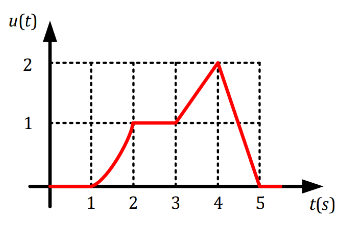

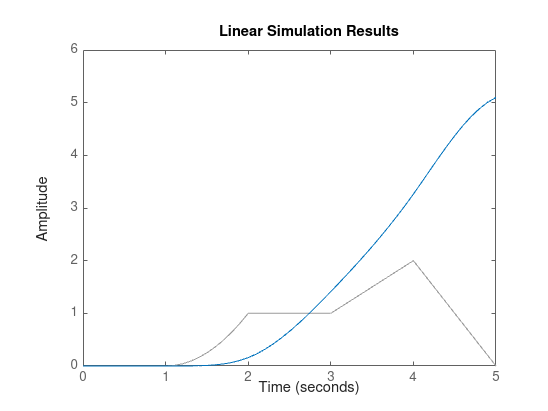

%Creamos las funciones a trozos de cada intervalo.
t = 0:0.1:5;

intervalo1 = zeros(10);

intervalo2 = 1.1:0.1:2;
parabola = intervalo2.^2 - 2*intervalo2 +1;

escalon = ones(1, 10);

intervalo4 = 3.1:0.1:4;
rampa = intervalo4 - 2;

rampa2 = 1.8:-0.2:0;

%Creo el vector entrada para el comando lsim.
entrada = [constante1 parabola escalon rampa rampa2];

%Dibujo la figura con lsim, que da directamente la respuesta
%de la funcion de transferenci G.
figure; hold on
lsim(G,entrada, t); hold off